ls = 3;
li = -3;
press = 3;
current_time = round(second(datetime("now")));
rng(current_time);
Nb = ceil(log((ls - li) * 10^press) + 0.9);
Np = 50; % corresponde a la población
var = 2;
num = randi([0 1], Np, var * Nb); % Población inicial
disp('Población inicial')

Población inicial


disp(num)

     1     0     1     1     0     1     0     1     1     1     0     0     0     0     0     0     0     0     1     0
     1     1     1     1     0     0     0     0     1     1     0     1     0     0     0     0     0     0     0     1
     1     0     0     1     1     1     0     1     1     0     0     1     0     0     0     1     0     0     1     0
     0     1     1     1     1     1     1     1     0     0     1     0     1     0     0     0     0     0     0     0
     1     1     0     0     0     1     1     0     0     1     1     0     0     1     1     0     1     0     1     0
     1     0     1     1     1     0     1     0     0     0     0     1     0     1     1     0     0     1     1     0
     1     1     1     0     1     1     1     0     0     1     0     1     1     1     1     0     1     0     0     1
     1     1     0     0     1     1     0     0     0     1     0     0     1     1     1     1     1     0     0     0
     0     1     1     0     1  

n_padres = Np / 2;
iteraciones = 49;
reales=debinarioReal(num, Np, Nb, var, li, ls);
disp('Números reales generados')

Números reales generados


disp(reales)

    1.2639   -2.9883
    2.6481   -1.4927
    0.6950   -1.3930
   -0.0205    0.7537
    1.6510    0.6246
    1.3636   -0.9003
    2.5894   -0.1320
    1.7918   -1.5455
   -0.4545    2.6305
   -1.5161    1.7273
    1.9091   -1.0235
    2.4721    2.2082
    1.0997    1.3754
   -0.9589   -1.6158
   -1.6804    0.7947
   -1.0762   -2.6833
    0.5367    2.1496
    1.1525   -1.9032
   -1.0880   -0.9941
    2.9707   -1.1466
    2.2141    0.1496
   -1.7331   -2.1672
    1.6745   -0.1144
    1.1408    2.2786
   -1.9853   -2.7595
    0.3783    2.8768
   -2.9472   -1.1760
    1.2815    2.4663
   -2.5073    0.2551
    2.9824   -2.9531
   -0.2610   -1.0645
   -0.3372   -1.6276
   -0.9296    2.0205
    1.6217    1.1818
    0.4194   -2.4721
   -0.2375   -1.6276
    0.9238    0.7713
    0.6657   -1.6862
    1.3636   -0.2375
    1.0938   -2.0205
   -1.9619   -1.2698
    0.8182    1.3050
    0.2551   -1.3754
   -2.4487    0.4487
   -1.9501    2.2434
   -2.1437   -1.4223
    2.5543    2.2903
   -1.1877   

x = reales(:, 1);
    y = reales(:, 2);


for g = 1:iteraciones
    reales = debinarioReal(num, Np, Nb, var, li, ls);
    x = reales(:, 1);
    y = reales(:, 2);
    fx = funcionObj(x, y);
    normalizados = abs(fx / (min(fx) + 1));

    P = normalizados / sum(normalizados);
    Q = cumsum(P);

    padres = zeros(1, n_padres);
    selecciones = zeros(2, n_padres);
    hijos = zeros(Np, var * Nb);

    for i = 1:n_padres
        r1 = rand();
        padre1 = find(Q >= r1, 1);
        padre2 = padre1;

        while padre2 == padre1
            r2 = rand();
            padre2 = find(Q >= r2, 1);
        end

        selecciones(1, i) = padre1;
        selecciones(2, i) = padre2;
        cruza = rand();

        hijos((2 * i) - 1, 1:var * Nb / 2) = num(padre1, 1:var * Nb / 2);
        hijos((2 * i) - 1, var * Nb / 2 + 1:end) = num(padre2, var * Nb / 2 + 1:end);
        hijos(2 * i, 1:var * Nb / 2) = num(padre2, 1:var * Nb / 2);
        hijos(2 * i, var * Nb / 2 + 1:end) = num(padre1, var * Nb / 2 + 1:end);
    end

    for i = 1:Np
        for j = 1:var * Nb
            muta = rand();
            if muta >= 0.9
                hijos(i, j) = not(hijos(i, j));
            end
        end
    end

    num = hijos;
end
cadena = sprintf('Población obtenida despues de %d generaciones',iteraciones+1)

cadena = 'Población obtenida despues de 50 generaciones'

disp(cadena)

Población obtenida despues de 50 generaciones


disp(num)

     1     1     0     0     1     0     1     0     0     1     0     0     1     1     0     0     0     1     0     0
     0     1     1     0     0     1     1     0     0     0     0     1     0     0     1     0     1     0     1     0
     0     1     1     0     1     1     0     0     1     0     1     1     0     0     1     1     0     0     0     0
     0     1     1     0     1     1     0     0     1     1     1     1     0     0     0     0     0     0     0     0
     0     1     1     0     0     1     1     0     1     1     1     1     0     0     0     0     1     1     0     0
     0     1     1     1     1     0     1     0     1     1     0     0     0     0     1     1     1     0     1     0
     0     1     1     0     1     1     0     0     1     0     0     1     0     0     0     0     0     1     1     0
     0     1     1     1     1     0     1     0     1     1     0     0     0     0     0     0     0     0     1     1
     0     1     1     0     1  

reales_1 = debinarioReal(num, Np, Nb, var, li, ls);
disp('Números reales obtenidos')

Números reales obtenidos


disp(reales_1)

    1.7449   -1.8504
   -0.6070   -1.2522
   -0.4545    1.7859
   -0.4487    1.5044
   -0.5894    1.5748
   -0.1202   -2.6598
   -0.4545   -1.4633
   -0.1202   -2.9824
   -0.5543   -1.3930
   -0.7654   -0.9765
   -0.5543    1.8094
   -1.9501   -1.1584
   -1.2053   -0.5543
   -0.4018   -1.1173
   -0.2610   -1.2522
   -2.7595   -0.6070
    1.7859   -1.4927
   -0.6422   -1.3109
   -0.6774   -1.1818
   -0.6950   -1.3812
   -0.4370   -1.2170
   -0.7830   -1.3930
   -0.6950   -0.6070
   -0.2610   -1.4751
   -0.8475   -1.1466
   -0.4545   -1.4047
   -0.1144   -1.4985
    0.6481   -1.3695
    2.5191    2.4194
    2.7889   -2.8710
   -0.5015   -1.2874
   -0.6364   -2.7302
   -0.9296    1.7390
   -0.4545   -2.6540
   -0.3021   -1.1818
   -0.5015   -1.4868
   -0.4252   -1.1525
   -0.5367   -1.3167
   -0.1554    2.1965
   -0.6598   -0.7830
   -1.9560   -0.7419
   -2.1320   -1.1290
   -0.4311   -1.1642
   -1.0000    1.6510
   -1.2053   -1.4047
   -0.9003   -2.9941
   -0.4018   -0.7889
   -1.0000   

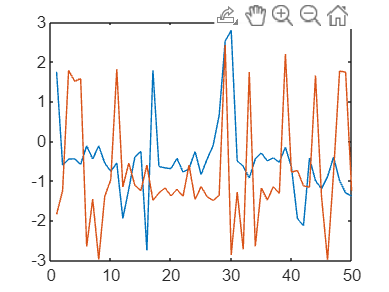

x_1 = reales_1(:, 1);
y_1 = reales_1(:, 2);
%plot(x_1)
%plot(y_1)
plot(reales_1)


%fx1= funcionObj(x,y);

%[maximo, indice] = max(fx)
%disp(reales(indice,1))
%disp(reales(indice,2))


disp('Mejor función objetivo')

Mejor función objetivo


fx_1= funcionObj(x_1,y-1)

fx_1 =     0.0956
    2.0837
    0.1581
    8.8584
    2.6184
    8.8419
    0.6212
    0.0092
    1.9573
    7.9481


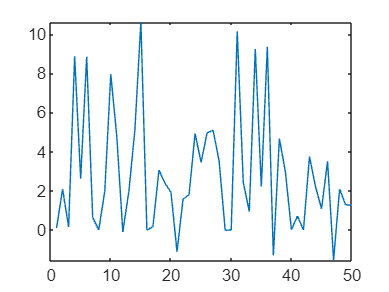

plot(fx_1)

[maximo_1, indice_1] = max(fx_1)

maximo_1 = 10.6113

indice_1 = 15

disp(reales(indice_1,1))

   -0.2610



disp(reales(indice_1,2))

   -0.6070



Funciones que se empelan

function reales = debinarioReal(num, Np, Nb, var, li, ls)
    desplazamiento = 1;
    reales = zeros(Np, var);
    
    for i = 1:var
        submatriz = num(:, desplazamiento:desplazamiento + Nb - 1);
        for k = 1:Np
            fila = 0;
            for j = 1:Nb
                fila = fila + (submatriz(k, j) * 2^(Nb - j));
            end
            reales(k, i) = li + (fila / (2^Nb - 1)) * (ls - li);
        end
        desplazamiento = desplazamiento + Nb;
    end
end

function resultado = funcionObj(x, y)
    resultado = 3 * (1 - x).^2 .* exp(-x.^2 - (y + 1).^2) + ...
        10 * (x / 5 - x.^3 - y.^5) .* exp(-x.^2 - y.^2) - ...
        1/3 * exp(-((x + 1).^2) - y.^2);
end